data = xlsread("Christoffer\Statastik\Opgaver Lektion\Lektion20\Data_M4STI1_2015F_reeksamen.xlsx", "A:B")

data =     5.0000    1.5820
    6.0000    1.8220
    3.4000    1.0570
    2.7000    0.5000
   10.0000    2.2360
    9.7000    2.3860
    9.5500    2.2940
    3.0500    0.5580
    8.1500    2.1660
    6.2000    1.8660


scatter(data(:,1), data(:,2))

mdl = fitlm(data(:,1), data(:,2))

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.13088      0.12599    1.0388       0.30971
    x1             0.24115     0.019049    12.659    7.5455e-12


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 0.236
R-squared: 0.874,  Adjusted R-Squared: 0.869
F-statistic vs. constant model: 160, p-value = 7.55e-12

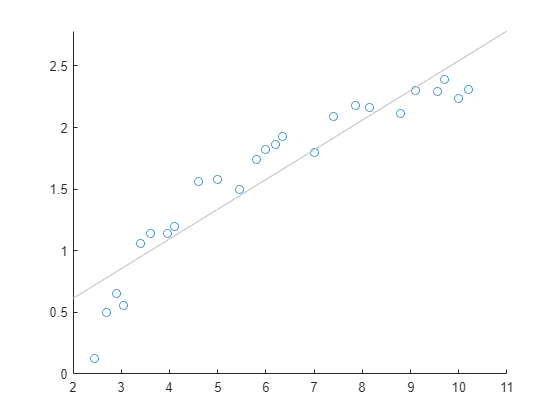

lsline

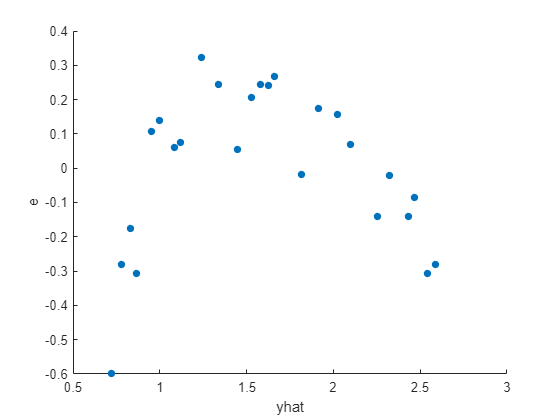

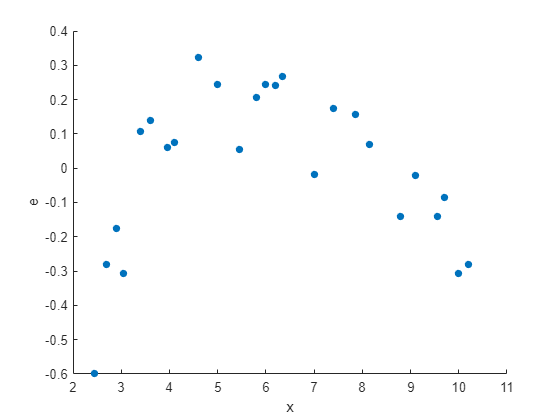

anal = struct with fields:
         data: [25×9 table]
            k: 1
            n: 25
    lev_limit: 0.1600
    rst_limit: 3



anal = STAT.Residual(mdl, data)


anal.data

ans = 25×9 table
     x        y        lev         rst       levrage    outlier     yhat             yci              resid  
    ____    _____    ________    ________    _______    _______    _______    __________________    _________

       5    1.582    0.048345      1.0689       0          0        1.3366     1.2293      1.444      0.24538
       6    1.822    0.040113      1.0588       0          0        1.5778       1.48     1.6756      0.24423
     3.4    1.057    0.088607     0.46323       0          0       0.95078    0.80543     1.0961      0.10622
     2.7      0.5     0.11671     -1.2892       0          0       0.78198    0.61516     0.9488     -0.28198
      10    2.23

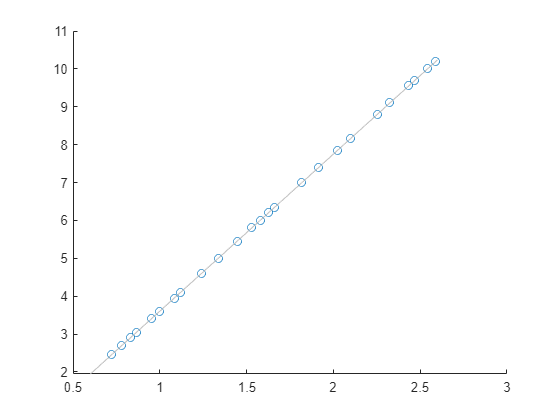


scatter(anal.data.yhat, data(:,1))
lsline


xlog = log(data(:,1))

xlog =     1.6094
    1.7918
    1.2238
    0.9933
    2.3026
    2.2721
    2.2565
    1.1151
    2.0980
    1.8245


xresi = 1./data(:,1)

xresi =     0.2000
    0.1667
    0.2941
    0.3704
    0.1000
    0.1031
    0.1047
    0.3279
    0.1227
    0.1613



mdl_log = fitlm(xlog, data(:,2))

mdl_log = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -0.83036     0.11083    -7.4925    1.2957e-07
    x1               1.4168    0.062336     22.728    2.9276e-17


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 0.138
R-squared: 0.957,  Adjusted R-Squared: 0.956
F-statistic vs. constant model: 517, p-value = 2.93e-17

xlog(:,2) = data(:,2)

xlog =     1.6094    1.5820
    1.7918    1.8220
    1.2238    1.0570
    0.9933    0.5000
    2.3026    2.2360
    2.2721    2.3860
    2.2565    2.2940
    1.1151    0.5580
    2.0980    2.1660
    1.8245    1.8660


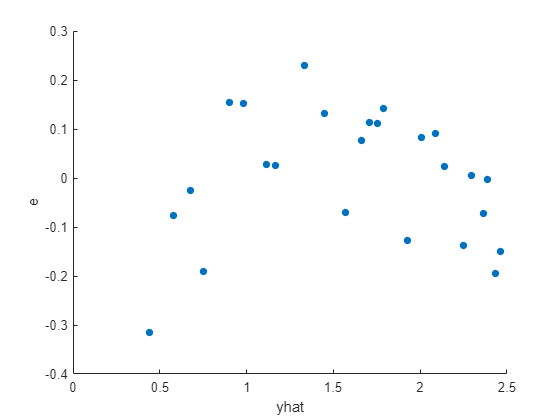

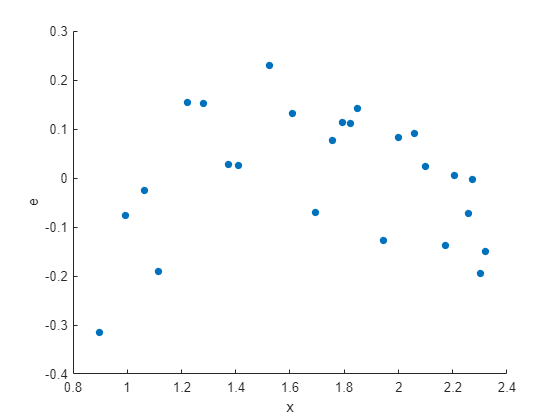

xlog_anal = struct with fields:
         data: [25×9 table]
            k: 1
            n: 25
    lev_limit: 0.1600
    rst_limit: 3
         fig1: [1×1 Figure]



xlog_anal = STAT.Residual(mdl_log, xlog)

xlog_anal.data

ans = 25×9 table
       x         y        lev          rst       levrage    outlier     yhat             yci              resid   
    _______    _____    ________    _________    _______    _______    _______    __________________    __________

     1.6094    1.582    0.042611      0.98098       0          0        1.4498     1.3911     1.5086       0.13215
     1.7918    1.822    0.040994      0.83962       0          0        1.7082     1.6505     1.7658       0.11385
     1.2238    1.057    0.091008       1.1807       0          0       0.90345     0.8176     0.9893       0.15355
    0.99325      0.5      0.1491     -0.59707       0          0       0.57685    0.46696    0.68674 


mdl_resi = fitlm(xresi, data(:,2))

mdl_resi = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     2.9789     0.044902     66.341    8.9177e-28
    x1             -6.9345      0.20643    -33.592    4.7425e-21


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 0.0942
R-squared: 0.98,  Adjusted R-Squared: 0.979
F-statistic vs. constant model: 1.13e+03, p-value = 4.74e-21

xresi(:,2) = data(:,2)

xresi =     0.2000    1.5820
    0.1667    1.8220
    0.2941    1.0570
    0.3704    0.5000
    0.1000    2.2360
    0.1031    2.3860
    0.1047    2.2940
    0.3279    0.5580
    0.1227    2.1660
    0.1613    1.8660


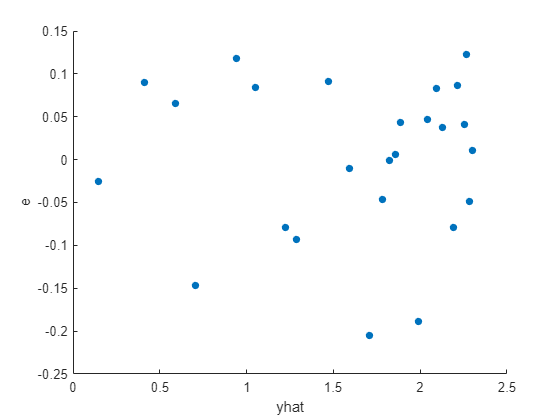

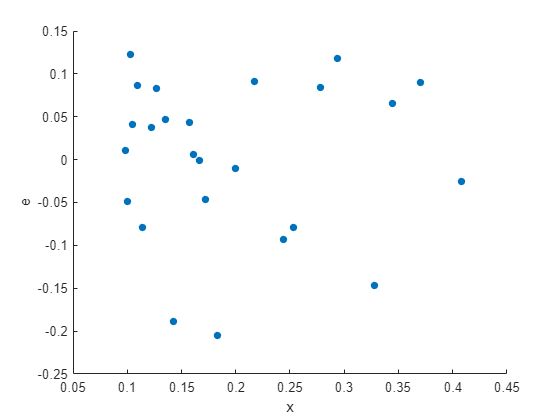

xresi_anal = struct with fields:
         data: [25×9 table]
            k: 1
            n: 25
    lev_limit: 0.1600
    rst_limit: 3
         fig1: [1×1 Figure]



xresi_anal = STAT.Residual(mdl_resi, xresi)

xresi_anal.data

ans = 25×9 table
       x         y        lev          rst       levrage    outlier     yhat             yci              resid   
    _______    _____    ________    _________    _______    _______    _______    __________________    __________

        0.2    1.582    0.040031      -0.1055       0          0         1.592      1.553     1.6309    -0.0099507
    0.16667    1.822    0.044555    -0.011712       0          0        1.8231      1.782     1.8642    -0.0011023
    0.29412    1.057    0.084899       1.3282       0          0       0.93929    0.88253    0.99605       0.11771
    0.37037      0.5     0.18368       1.0543       1          0       0.41051    0.32702      0.494 